clear all; 

# Exercise 3.2 - Inverse Kinematic Algorithm

In this exercise you will setup an inverse kinematics algorithm using the pseudoinverse of the jacobian. 

Consider this UR3e robot: 

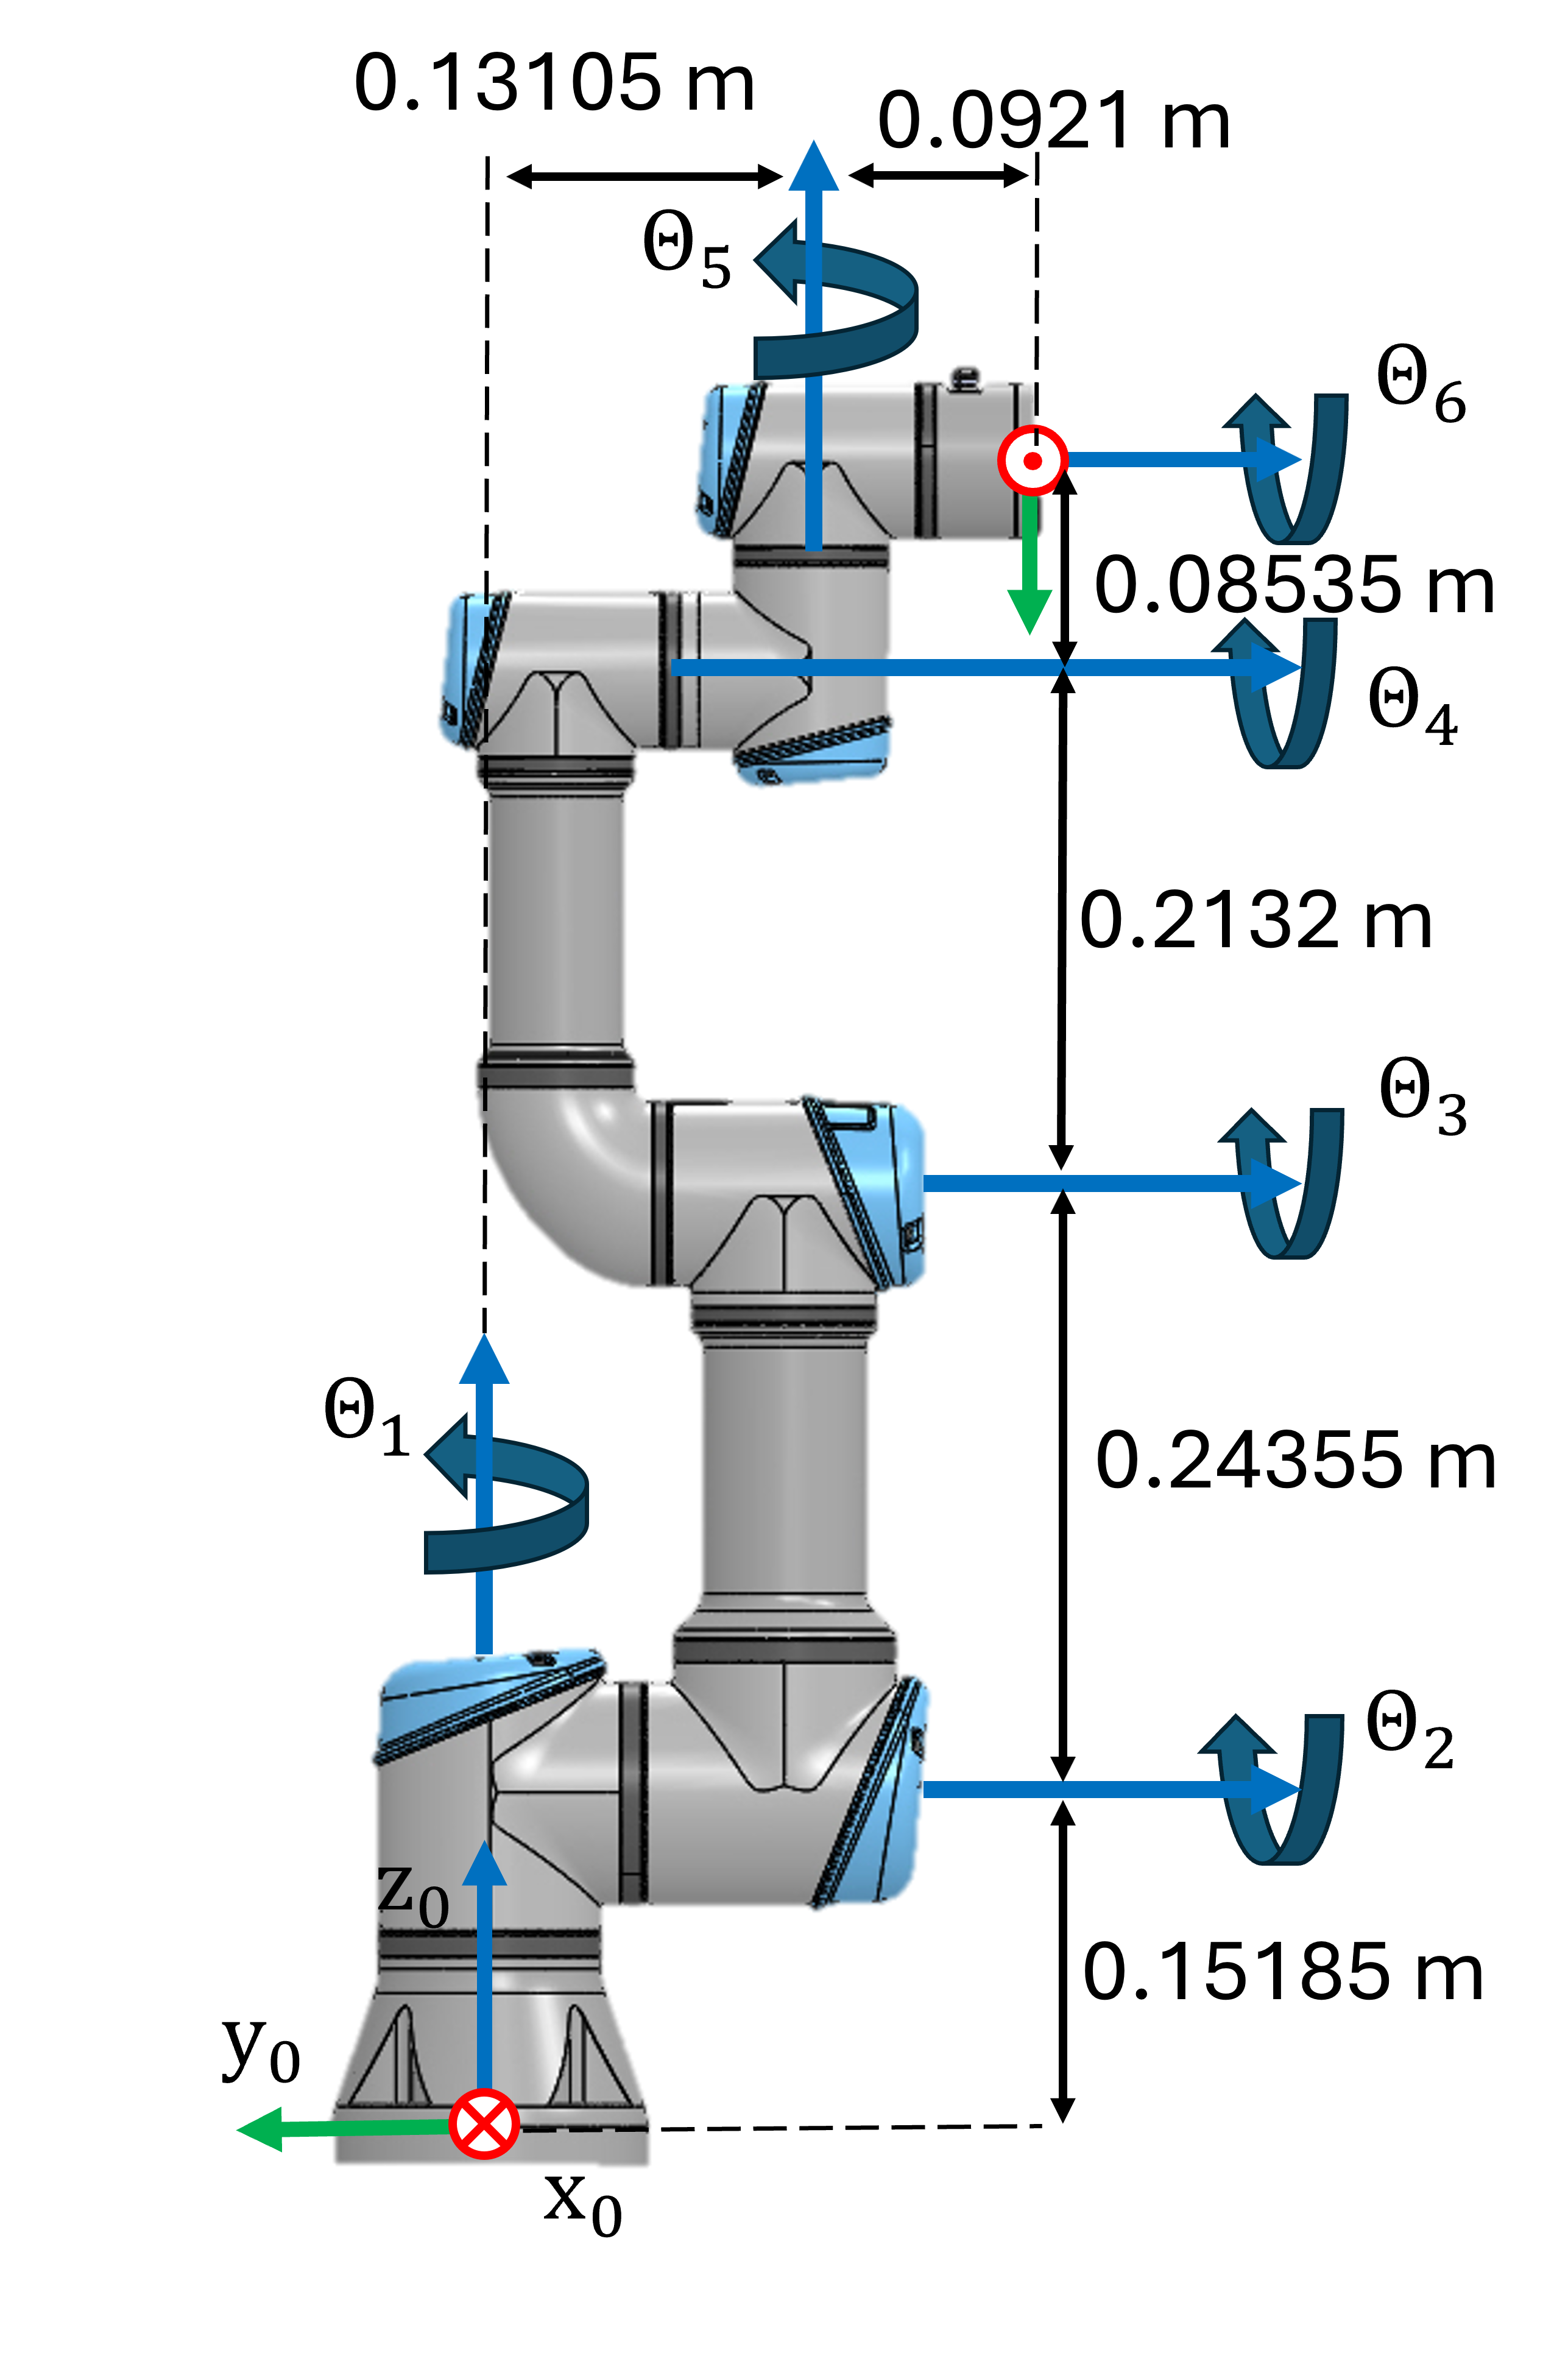

Consider this DH table for the UR3e: 

The control scheme you have to implement is: 

where $k\left(\cdot \right)$ is the forward kinematic of the q. 

## Task 1

Write a function that computes a solution to the inverse kinematic using the pseudoinverse of the Jacobian. The function has the following inputs: 

- the initial joint states as a row vector ($q_0 \in {\mathbb{R}}^{6\textrm{x1}}$)

- desired pose vector using euler angles (ZYZ) $x_{\textrm{desired}} =\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\phi \\
\theta \\
\psi 
\end{array}\right\rbrack$

- gain (k) 

- tolerance (tol)

- max iterations (Imax)

The function should return the required joint states as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

For this task, consider $\dot{x_d } =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$ and $\Delta t=0\ldotp 01\;s$

Use the following function name for your solution:

-  PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

You may use the function below to compute the symbolic transform from the base to the endeffector. 

- dh2tf()

Solve this exercise without using the function: 

- inverseKinematics()

function q = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)
syms q1 q2 q3 q4 q5 q6 real
DH=[
   %a       alpha       d       theta
   0        pi/2        0.15185  q1;
   -0.24355 0           0       q2;
   -0.2132  0           0       q3;
   0        pi/2        0.13105 q4;
   0        -pi/2       0.08535 q5;
   0        0           0.0921  q6;
    ];

$$DH = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & \frac{3037}{20000} & q_{1}\\ -\frac{4871}{20000} & 0 & 0 & q_{2}\\ -\frac{533}{2500} & 0 & 0 & q_{3}\\ 0 & \frac{\pi }{2} & \frac{2621}{20000} & q_{4}\\ 0 & -\frac{\pi }{2} & \frac{1707}{20000} & q_{5}\\ 0 & 0 & \frac{921}{10000} & q_{6} \end{array}\right)$$


T06 = dh2tf(DH); 


q=[]; 

end


You can check your work by clicking the Run: 

 
check_exercise('3-2-1')

## Task 2

Extend your function from before. 

Add the input: 

- dt (time for discrete algorithm step)

Add the outputs: 

- total_time (time it takes for the algorithm to find a solution)

- total_iterations (iterations until the solution was found)

- solution_error (the pose square error for the solution configuration$\left({\textrm{error}}_{\textrm{solution}} \left(q\right)={e\left(q\right)}^T \cdot e\left(q\right)\right)$)

Use "tic" and "toc" to measure the computational time. 

Use the following function name for your solution:

-  ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

Solve this exercise without using the function: 

- inverseKinematics()

function [q,total_time,total_iterations,solution_error] = ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

q=[]; 
total_time = []; 
total_iterations=[]; 
solution_error = []; 

end

Analyze how your algorithm behaves when you change the tolerance, gain or timestep. 